## Pablo Vega Gallego, VC, FIB.

# Sessió 1

En aquesta sessió realitzarem l'exercici proposat i mirarem de posar un exemple de per a què podria servir aquest codi.

Comencem per la creació dels punts, en aquest cas hem decidit fer servir un núvol de punts totalment aleatori, fent servir la funció 'rand' de matlab.

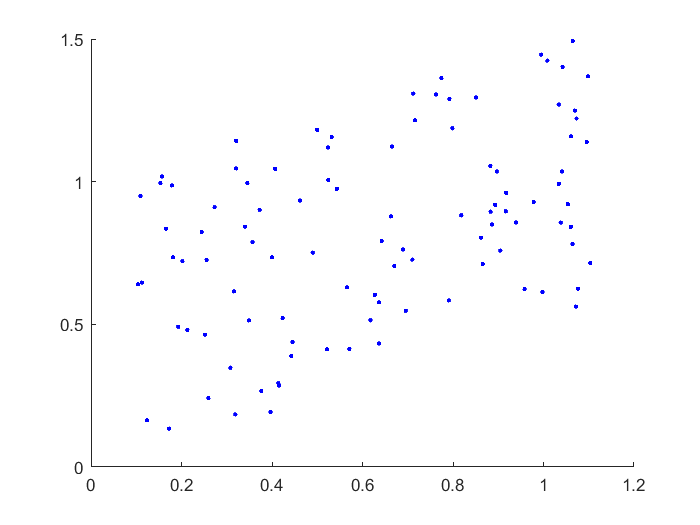

x = rand(1, 100) + rand();
y = rand() .* x + rand(1, 100);
scatter(x, y, '.', 'b');

Després, centrarem aquests punts a l'origen de coordenades.

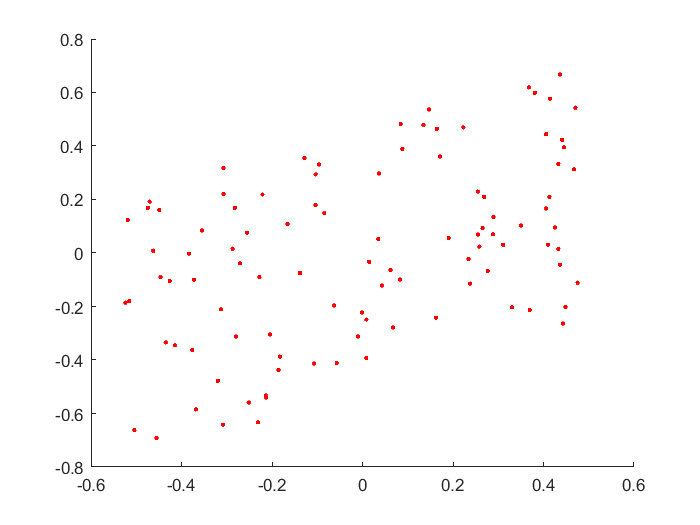

nx = x - mean(x);
ny = y - mean(y);
figure
scatter(nx, ny, '.', 'r');

Realitzarem el càlcul de la matriu de covariança per més tard trobar els eigenvector (vectors propis) i els eigenvalues (valors propis), per més tard poder trobar els eixos del nostre model. Aprofitarem que la matriu de covariança és simètrica i ens asegurarem que podem trobar uns valors.

c = cov(nx, ny);
[evectors, evalues] = eig(c);

Valors de les variables...

disp(c);

    0.0998    0.0471
    0.0471    0.1056



disp(evectors);

   -0.7284    0.6851
    0.6851    0.7284



disp(evalues);

    0.0555         0
         0    0.1499



Farem una impressió dels eixos i dels punts.

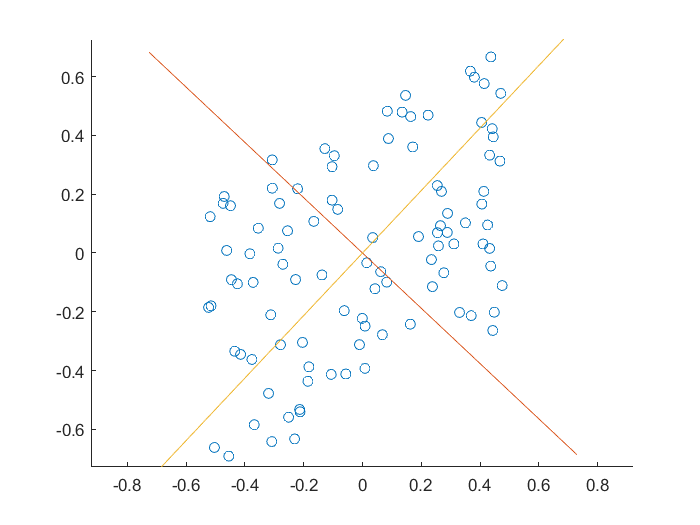

figure
hold on
escala = 1;
%axis equal
scatter(nx, ny);
axis equal
plot([evectors(1, 1)*-escala, evectors(1, 1)*escala], [evectors(1, 2)*-escala, evectors(1, 2)*escala]);
plot([evectors(2, 1)*-escala, evectors(2, 1)*escala], [evectors(2, 2)*-escala, evectors(2, 2)*escala]);
hold off

Ara, calcularem l'angle de rotació per tal de tenir els punts alineats amb els eixos i girarem fent servir la matriu de rotació.

[value, ind] = max(diag(evalues));
theta = -pi/2 - atan2(evectors(ind, 2), evectors(ind, 1));
disp(theta);

   -2.3868



R = [cos(-theta), sin(-theta); -sin(-theta), cos(-theta)];
rp = R * [nx; ny]

rp =     0.0090   -0.1385   -0.0596   -0.1279    0.2774    0.4626    0.1988   -0.4155   -0.1320   -0.2091   -0.3484   -0.5037   -0.3793    0.1567   -0.1641   -0.1849    0.2377   -0.1296    0.0106    0.3427    0.2693   -0.1861   -0.0871   -0.1422    0.3747    0.1590    0.2608   -0.1142    0.0258   -0.0534   -0.1264    0.3108    0.4746    0.1390    0.2967   -0.2149   -0.2155   -0.2776   -0.4648    0.0879   -0.0315    0.2028   -0.2478    0.0933    0.2629   -0.2448    0.3214    0.4409    0.0658   -0.0335
   -0.6016   -0.2251    0.3617    0.0158    0.2646    0.2653   -0.0599   -0.0981    0.6782    0.5345   -0.2666   -0.1117   -0.0789   -0.7027    0.4453   -0.3149    0.1197   -0.2497   -0.0620    0.3104   -0.4095   -0.1444   -0.5392    0.8155    0.0498   -0.4947   -0.4912    0.0594    0.5217   -0.5929   -0.5485   -0.0079    0.1824   -0.7854   -0.1755    0.6792    0.5394   -0.3033   -0.1604    0.5415   -0.6105   -0.3442   -0.1406   -0.7039    0.3720   -0.3612    0.0704   -0.0204    0.5357    

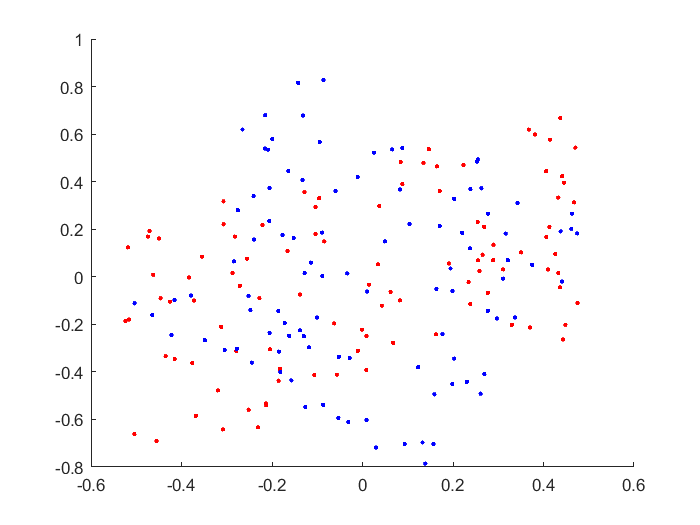

figure
hold on
scatter(nx, ny, '.', 'r');
scatter(rp(1, :), rp(2, :), '.', 'b');
hold off

Ara per tal de veure la utilitat d'aquest sistema carregarem una imatge com aquesta:

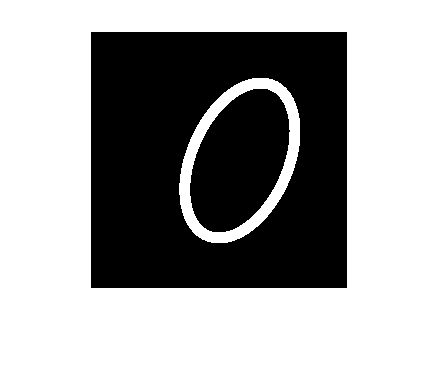

I = imread('oval.png');
circulo = im2bw(I, 0);
imshow(circulo);

Ara tractarem la imatge com si fos un gràfic de punts com el vist anteriorment.

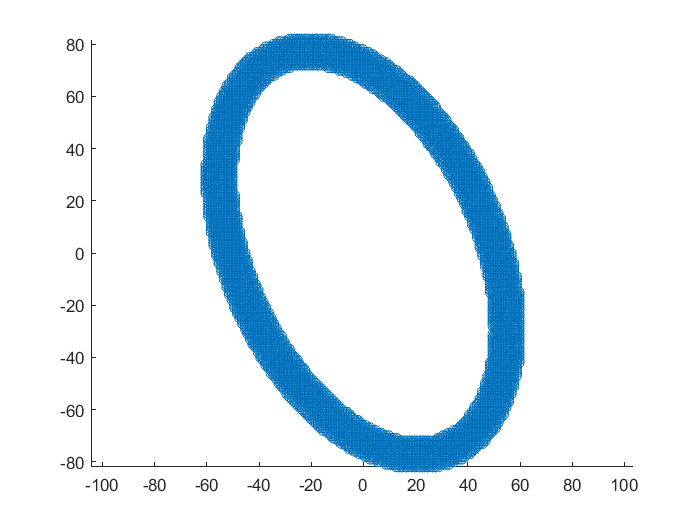

[y, x] = find(I);

nx = x - mean(x);
ny = y - mean(y);

nx = nx';
ny = ny';

figure
hold on
axis equal
scatter(nx, ny);
hold off

Aplicarem els mateixos mètodes que abans.

cc = cov(ncx, ncy);
[cevectors, cevalues] = eig(cc);

figure
hold on
cescala = 10;
axis equal
scatter(ncx, ncy);
axis equal
plot([cevectors(1, 1)*-cescala, cevectors(1, 1)*cescala], [cevectors(1, 2)*-cescala, cevectors(1, 2)*cescala]);
plot([cevectors(2, 1)*-cescala, cevectors(2, 1)*cescala], [cevectors(2, 2)*-cescala, cevectors(2, 2)*cescala]);
hold off
[cvalue, cind] = max(diag(cevalues));
ctheta = -pi/2 - atan2(cevectors(cind, 2), cevectors(cind, 1));

cR = [cos(-ctheta), sin(-ctheta); -sin(-ctheta), cos(-ctheta)];
crp = cR * [ncx; ncy]

crp =    46.2029   45.8048   45.4067   45.0086   44.6105   44.2123   43.8142   43.4161   43.0180   42.6199   42.2217   41.8236   48.8687   48.4706   48.0725   47.6743   47.2762   46.8781   46.4800   46.0819   45.6837   45.2856   44.8875   44.4894   44.0912   43.6931   43.2950   42.8969   42.4988   42.1006   41.7025   41.3044   40.9063   40.5082   40.1100   39.7119   39.3138   38.9157   38.5176   38.1194   37.7213   37.3232   36.9251   50.3401   49.9420   49.5438   49.1457   48.7476   48.3495   47.9514
   45.1370   46.0543   46.9716   47.8890   48.8063   49.7236   50.6410   51.5583   52.4756   53.3930   54.3103   55.2276   36.4828   37.4002   38.3175   39.2348   40.1522   41.0695   41.9868   42.9042   43.8215   44.7388   45.6562   46.5735   47.4908   48.4082   49.3255   50.2428   51.1602   52.0775   52.9948   53.9122   54.8295   55.7468   56.6642   57.5815   58.4988   59.4162   60.3335   61.2508   62.1682   63.0855   64.0028   30.5807   31.4981   32.4154   33.3327   34.2501   35.1674   

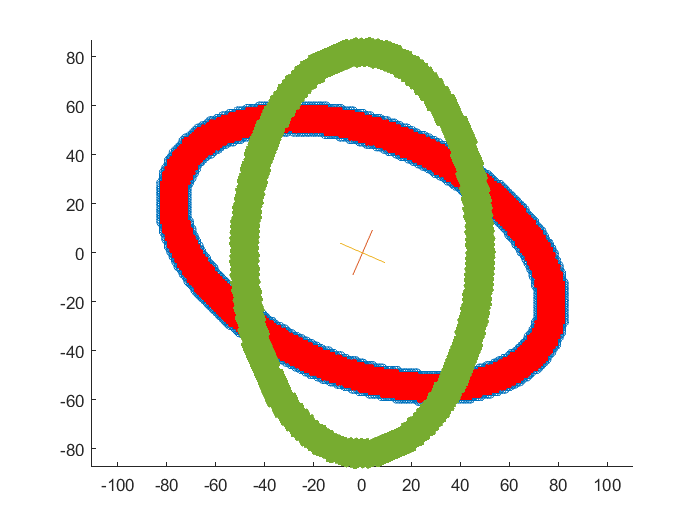


hold on
scatter(ncx, ncy, '.', 'r');
scatter(crp(1, :), crp(2, :), '.');